   NaN



   NaN



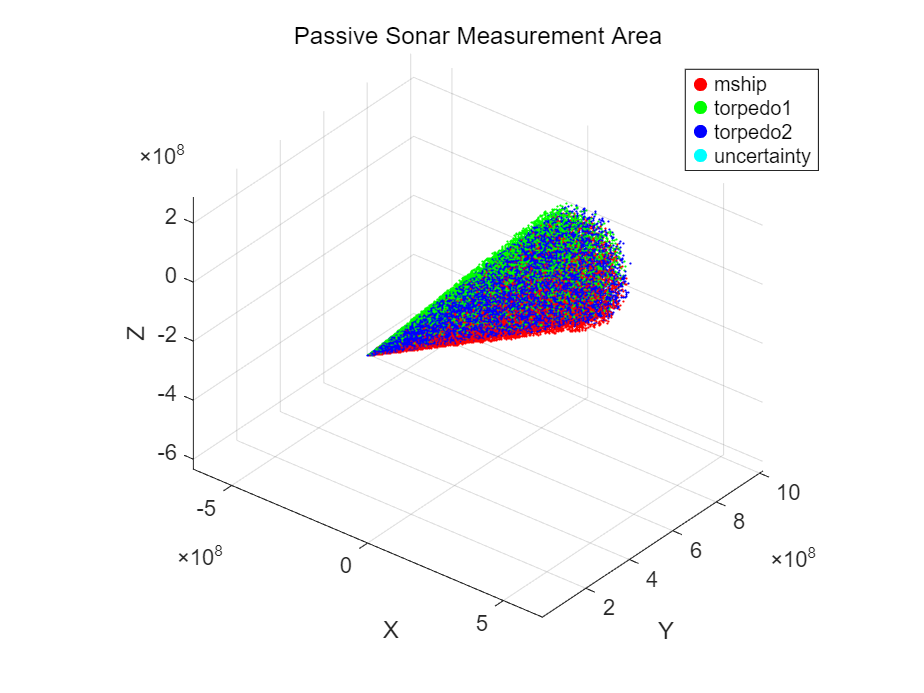

   NaN



   NaN



   NaN



   NaN



   NaN



   NaN



   NaN



   NaN




clc; clear; close all;
CDN = zeros(1000, 1);
%% Sensor / Target initialize

% 패시브 소나와 EKF를 이용한 방위각 기반 타겟 위치 추정 알고리즘
% 두개의 어뢰와 모선에 있는 소나 센서를 이용
% State=[x y z vx vy vz]'
% measurement=[b e]'각각 방위각, 양각 
% 필터 :  EKF
load("m_10.mat")% trajectory 파일들은 따로 생성 후 관리. 이 파일 안에 trajectories.target 형태로 저장.
% 새로 만들거나 수정할 때는 그냥 matlab에서 trajectories.target=[0 0 0; 1 1 1; ...] 이렇게 추가하면됨
target=initializeTarget([90 -20],15,DOPgoodtrajectories1.target); % [azimuth elevation](deg) velocity trajectory

%% Mothership and Torpedoes initialization
mship=initializeSensor(20,1000000000,10,target,DOPgoodtrajectories1.mship);%v,maxD,noise(deg),target,trajectory
torpedo1=initializeSensor(20,1000000000,10,target,DOPgoodtrajectories1.torpedo1);%v,maxD,noise(deg),target,trajectory
torpedo2=initializeSensor(20,1000000000,10,target,DOPgoodtrajectories1.torpedo2);%v,maxD,noise(deg),target,trajectory

%% Simulation

for i=1:1:length(target.traj)
    updateSimulation(target);
    updateSimulation(mship);
    updateSimulation(torpedo1);
    updateSimulation(torpedo2);
    [uncertainArea, condNum] = findUncertaintyArea(mship.sonar, torpedo1.sonar, torpedo2.sonar, 0.1);
    CDN(i,1) = condNum;
    disp(condNum)
    % Visualization
    figure; hold on;
    scatter3(mship.sonar.points(:, 1), mship.sonar.points(:, 2), mship.sonar.points(:, 3), 1, 'filled', 'r');
    scatter3(torpedo1.sonar.points(:, 1), torpedo1.sonar.points(:, 2), torpedo1.sonar.points(:, 3), 1, 'filled', 'g');
    scatter3(torpedo2.sonar.points(:, 1), torpedo2.sonar.points(:, 2), torpedo2.sonar.points(:, 3), 1, 'filled', 'b');
    scatter3(uncertainArea(:, 1), uncertainArea(:, 2), uncertainArea(:, 3), 10, 'filled', 'c'); % 겹치는 영역 표시

    title('Passive Sonar Measurement Area');
    xlabel('X'); ylabel('Y'); zlabel('Z');
    legend('mship', 'torpedo1', 'torpedo2', 'uncertainty');
    axis equal;
    grid on;
    view([40 -50 40]);
    hold off;

end



%% Functions
%모델 초기화
function target=initializeTarget(heading,v,trajectory)
    target.vel = v; % 속력
    target.heading = [deg2rad(heading(1)) deg2rad(heading(2))]; % 헤딩각
    target.Pos = trajectory(1,:);
    target.PosIdx=1;
    target.State = [target.Pos, ...
    target.vel * cos(target.heading(2)) * cos(target.heading(1)), ...
    target.vel * cos(target.heading(2)) * sin(target.heading(1)), ...
    target.vel * sin(target.heading(2))]'; % 상태 변수
    target.traj=trajectory;
end

function tracker=initializeSensor(v,maxD,noise,target,trajectory)
    tracker.vel = v;
    tracker.Pos = trajectory(1,:);
    tracker.PosIdx=1;
    tracker.heading = [atan2(target.Pos(2) - tracker.Pos(2), target.Pos(1) - tracker.Pos(1)), ...
        atan2(target.Pos(3) - tracker.Pos(3), norm(target.Pos(1:2) - tracker.Pos(1:2)))];
    tracker.State = [tracker.Pos, ...
        tracker.vel * cos(tracker.heading(2)) * cos(tracker.heading(1)), ...
        tracker.vel * cos(tracker.heading(2)) * sin(tracker.heading(1)), ...
        tracker.vel * sin(tracker.heading(2))]';
    % 센서 업데이트 (원뿔 생성)
    tracker.sonar = updateSensor(maxD, noise, tracker.State(1:3), tracker.heading);
    tracker.traj=trajectory;
end
function updateSimulation(model)
    model.PosIdx=model.PosIdx+1;
    model.Pos=model.traj(model.PosIdx,:);
end